# Interpolation

## Structure data

clear all; clc; addpath('./functions/')
load('../1-Cleaning/data/dc_corr.mat'); 
load('../2-Inference/data/Density_inference.mat');
load('./data/Density_crossValidation.mat')

## Interpolation

Define the ratio distance/time for the interpolation (eg. 1 day = 1degree lat/lon). This value as been optimized with the data (see section below).

ratio_coord_time= 13;

Estimation

for i_d=1:numel(dc)
  
  sim = i_d==data.radar;
  
  Fnn = scatteredInterpolant(data.lat(~sim),data.lon(~sim),data.time(~sim).*ratio_coord_time,data.dens(~sim),'nearest');
  Fl = scatteredInterpolant(data.lat(~sim),data.lon(~sim),data.time(~sim).*ratio_coord_time,data.dens(~sim),'linear');
  Fn = scatteredInterpolant(data.lat(~sim),data.lon(~sim),data.time(~sim).*ratio_coord_time,data.dens(~sim),'natural');
  
  interpo.nn(sim) = Fnn(data.lat(sim),data.lon(sim),data.time(sim).*ratio_coord_time);
  interpo.l(sim) = Fl(data.lat(sim),data.lon(sim),data.time(sim).*ratio_coord_time);
  interpo.n(sim) = Fn(data.lat(sim),data.lon(sim),data.time(sim).*ratio_coord_time);

end

## Figure

Visual figure

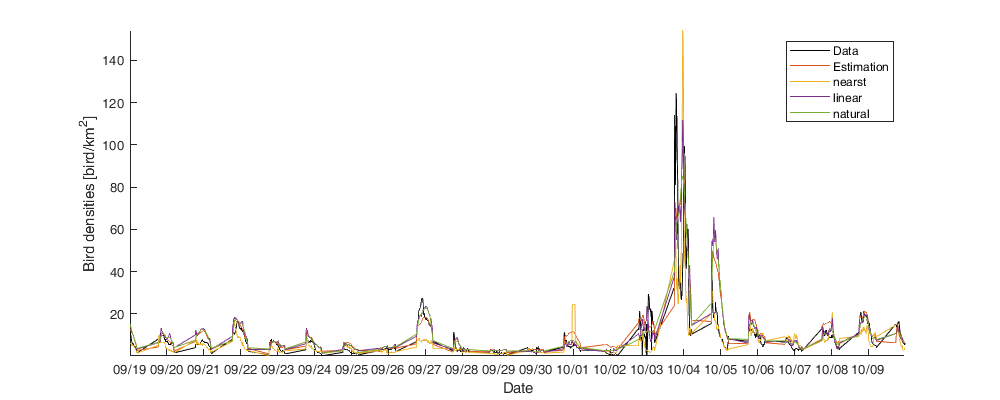

i_d=50;
figure('position',[0 0 1000 400]); hold on;
id=data.radar==i_d;
plot(data.time(id),data.dens(id),'k');
plot(data.time(id),cc.dens_est(id))
plot(data.time(id),interpo.nn(id));
plot(data.time(id),interpo.l(id));
plot(data.time(id),interpo.n(id));
datetick('x');axis tight; xlabel('Date'); ylabel('Bird densities [bird/km^2]'); legend('Data','Estimation','nearst','linear','natural');

RMSE

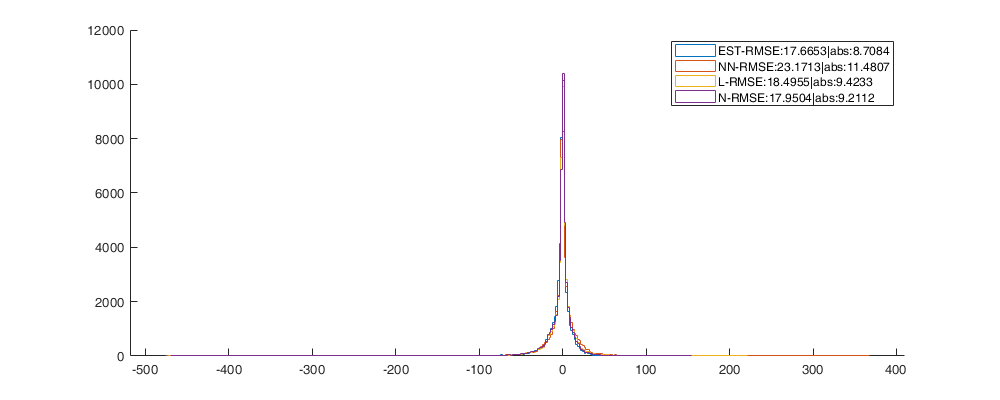

figure('position',[0 0 1000 400]); hold on;
histogram(cc.dens_est - data.dens,'DisplayStyle', 'stairs','DisplayName',['EST-RMSE:' num2str(sqrt(nanmean((cc.dens_est - data.dens).^2))) '|abs:' num2str(nanmean(abs(cc.dens_est - data.dens)))]);
histogram(interpo.nn - data.dens,'DisplayStyle', 'stairs','DisplayName',['NN-RMSE:' num2str(sqrt(nanmean((interpo.nn - data.dens).^2))) '|abs:' num2str(nanmean(abs(interpo.nn - data.dens)))]);
histogram(interpo.l - data.dens,'DisplayStyle', 'stairs','DisplayName',['L-RMSE:' num2str(sqrt(nanmean((interpo.l - data.dens).^2))) '|abs:' num2str(nanmean(abs(interpo.l - data.dens)))]);
histogram(interpo.n - data.dens,'DisplayStyle', 'stairs','DisplayName',['N-RMSE:' num2str(sqrt(nanmean((interpo.n - data.dens).^2))) '|abs:' num2str(nanmean(abs(interpo.n - data.dens)))]);
legend

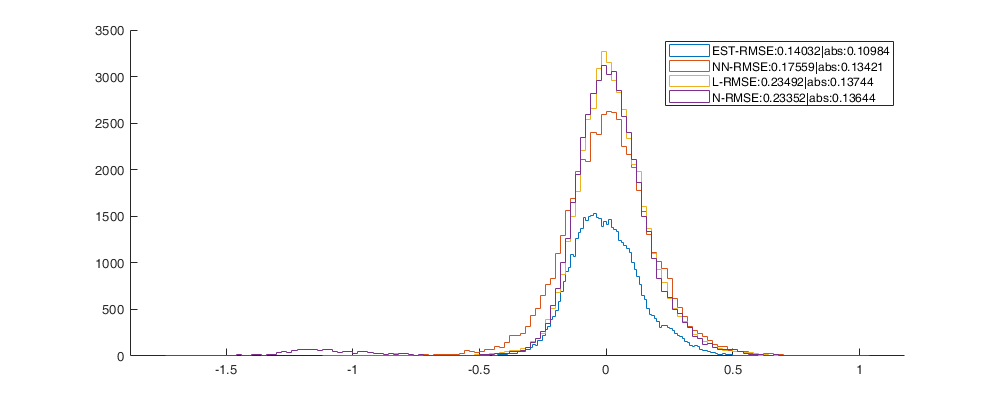

figure('position',[0 0 1000 400]); hold on;
histogram(cc.denst_est - data.denst,'DisplayStyle', 'stairs','DisplayName',['EST-RMSE:' num2str(sqrt(nanmean((cc.denst_est - data.denst).^2))) '|abs:' num2str(nanmean(abs(cc.denst_est - data.denst)))]);
histogram(max(interpo.nn,0).^pow_a - data.denst,'DisplayStyle', 'stairs','DisplayName',['NN-RMSE:' num2str(sqrt(nanmean((max(interpo.nn,0).^pow_a - data.denst).^2))) '|abs:' num2str(nanmean(abs(max(interpo.nn,0).^pow_a - data.denst)))]);
histogram(max(interpo.l,0).^pow_a - data.denst,'DisplayStyle', 'stairs','DisplayName',['L-RMSE:' num2str(sqrt(nanmean((max(interpo.l,0).^pow_a - data.denst).^2))) '|abs:' num2str(nanmean(abs(max(interpo.l,0).^pow_a - data.denst)))]);
histogram(max(interpo.n,0).^pow_a - data.denst,'DisplayStyle', 'stairs','DisplayName',['N-RMSE:' num2str(sqrt(nanmean((max(interpo.n,0).^pow_a - data.denst).^2))) '|abs:' num2str(nanmean(abs(max(interpo.n,0).^pow_a - data.denst)))]);
legend

Save

save('data/Cross-validation_interpo.mat','interpo');

## Calibrate` ratio_coord_time`

ratio_coord_time =    1000 *[ 0.0184    0.1006   -0.0024   -0.0007   -0.0013    0.0154    0.5188    0.0236    0.3456    0.0125    0.1205    0.1871    0.0738    0.1084    0.0266    0.0090    0.0036    0.6481   -0.0017    0.0131    0.3464 0.0130    0.9928    0.0130    0.0899    0.0130    0.0130    0.2673    0.0181    0.0202    2.4713    0.0571    0.5818    0.5503    0.0130    0.1414    0.0839    0.0040    0.1486    0.0179    0.0130    0.0130 0.4111    0.0040    0.0130    0.0130    0.1771   -0.0013    0.1080    0.0108    0.0235    0.0130    0.0074    0.0148    0.0332   -0.0013    0.0130   -0.0013    0.0091    0.0039   -0.0013    0.0388    0.0130 -0.0013    0.0104    0.0052    0.0039   -0.0013    0.0123];

parfor i_d=1:numel(dc)
  id1=find(D(i_d,:)>distlelim);
  id2=ismember(data.i_d,id1);
  id3=data.i_d==i_d;
  
  interpolafx =@(x) griddata(data.lat(id2),data.lon(id2),data.time(id2).*x,data.dens(id2),data.lat(id3),data.lon(id3),data.time(id3).*x,'natural');
  rmse = @(x) nansum( (interpolafx(x)-data.dens(id3)).^2 );
  
  % options = optimset('PlotFcns',{@optimplotfval,@optimplotx},'MaxFunEvals',100);
  options = optimset('MaxFunEvals',30);
  ratio_coord_time(i_d) = fminsearch(rmse,ratio_coord_time(i_d),options)
  % ratio_coord_time = fminbnd(rmse,0,1,options);
end

Figure

figure; histogram(ratio_coord_time(ratio_coord_time>0 & ratio_coord_time<100),100); xlabel('ratio_coord_time');